# System Integration and Test Simulation

Configure a simulation that uses the following:

- Truth Locations - Field-collected ADSB data recorded with an RTL-SDR

- Detections and Sensor-based Tracks:

- Active radar (fusionRadarSensor)

- ADSB data (gpsSensor and ADSBReceiver)

- TrackFuser for C2 level tracks

- OSPA Metric, trackAssignmentMetrics, and errorMetrics for track accuracy analysis

close all force
clear

## Setup Scenario

Import truth location of aircraft and convert to trajectories for simulation

mapOrigin = [42.39423231362 -70.95934958874 0]; % Hard-coded this into radar2central and central2radar
load("C:\Users\pwilliam\OneDrive - MathWorks\Documents\SFTT\SFTTWorkshopPart2\Scenario\TrackingScenarioTruth.mat")

Scenario Creation includes configuring the Active Radar Sensor

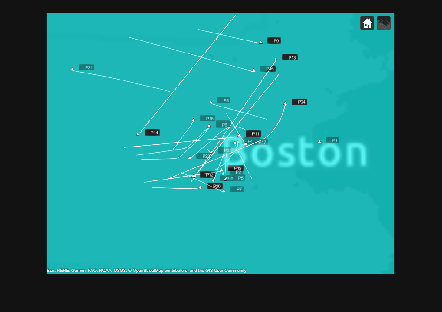

scenario = helperCreateScenario(tuningData,mapOrigin);
mapViewer = trackingGlobeViewer('ReferenceLocation',mapOrigin,'Basemap','streets-dark');
campos(mapViewer, mapOrigin + [0 -0.4 1e5]);
drawnow;
plotScenario(mapViewer,scenario);
snapshot(mapViewer);

## Secondary Sensor Configuration

Add ADSB for secondary target detection

Commercial planes are all equipped with GPS receivers. As the backbone of ADS-B, the accuracy of onboard GPS can be set to conform with ADS-B requirements. The Navigation Accuracy Category used in ADS-B, for position and velocity are referred to as NACp and NACv, respectively. Per FAA regulation[1], the NACp must be less than 0.05 nautical miles and the NACv must be less than 10 meters per second. In this example, you use a gpsSensor model with a position accuracy of 50 m and a velocity accuracy of 10 m/s to configure the adsbTransponder model

llaADSBTower = ned2lla(scenario.Platforms{2}.Position,mapOrigin,'flat');

% ADSB passive receiver
horAccuracy = 20; % meters
vertAccuracy = 50; % meters
velAccuracy = 0.4; % m/s

gps = gpsSensor('PositionInputFormat','Geodetic',...
    'HorizontalPositionAccuracy',horAccuracy,...
    'VerticalPositionAccuracy', vertAccuracy,'VelocityAccuracy',velAccuracy);
numTargets = numel(scenario.Platforms)-2; % two platforms in scene are the sensor towers

Leverage a helper function to store GPS transponder in a structure.

transponderStruct = helperCreateTX(numTargets,gps);

## Configure ADSB Receiver

You use `adsbReceiver` to model the reception of ADS-B messages. An ADS-B message contains the position measured by the airplane own GPS instrument. The message is usually encoded and broadcasted on 1090 MHz channel for nearby ADS-B receivers to pick up. You define a reception range of 200 km around each surveillance station. In this example you assume that  surveillance stations have perfect communication between each other. Therefore, a central receiver picks up broadcasted ADS-B messages within range of at least one station.

% Define central adsbReceiver
adsbRx = adsbReceiver('ReceiverIndex',2);
adsbRange = 2e5;

## **Configure Tracker**

### Specify Aircraft Types

The first step in defining the tracker requires specifying the types of objects you want to track. In this example, these objects are passenger aircraft, general aviation aircraft, and helicopters. Use the [`trackerTargetSpec`](docid:fusion_ref#mw_d12c6e07-1099-4b7b-b09f-3be62d29245e) function to create a target specification for a passenger aircraft and observe the properties of the specification.

passengerSpec = trackerTargetSpec("aerospace","aircraft","passenger");
disp(passengerSpec)

  PassengerAircraft with properties:

           MaxHorizontalSpeed: 250    m/s 
             MaxVerticalSpeed: 20     m/s 
    MaxHorizontalAcceleration: 10     m/s²
      MaxVerticalAcceleration: 1      m/s²



generalAviationSpec = trackerTargetSpec("aerospace","aircraft","general-aviation")

generalAviationSpec =   GeneralAviation with properties:

           MaxHorizontalSpeed: 150    m/s 
             MaxVerticalSpeed: 15     m/s 
    MaxHorizontalAcceleration: 1      m/s²
      MaxVerticalAcceleration: 5      m/s²


helicopterSpec = trackerTargetSpec("aerospace","aircraft","helicopter")

helicopterSpec =   Helicopter with properties:

           MaxHorizontalSpeed: 80    m/s 
             MaxVerticalSpeed: 10    m/s 
    MaxHorizontalAcceleration: 5     m/s²
      MaxVerticalAcceleration: 1     m/s²


activeRadarSpec = trackerSensorSpec("aerospace","radar","monostatic")

activeRadarSpec =   AerospaceMonostaticRadar with properties:

           MaxNumLooksPerUpdate: 30    
    MaxNumMeasurementsPerUpdate: 10    

    IsPlatformStationary: 1                  
        PlatformPosition: [0 0 0]         m  
     PlatformOrientation: [3⨯3 double]       
        MountingLocation: [0 0 0]         m  
          MountingAngles: [0 0 0]         deg

       HasElevation: 1                
       HasRangeRate: 1                
        FieldOfView: [60 20]       deg
        RangeLimits: [0 1e+05]     m  
    RangeRateLimits: [-500 500]    m/s

      AzimuthResolution: 1      deg
        RangeResolution: 100    m  
    ElevationResolution: 5      deg
    RangeRateResolution: 10     m/s

    DetectionProbability: 0.9      
          FalseAlarmRate: 1e-06    


targetSpec = {passengerSpec,generalAviationSpec,helicopterSpec};

towerPosition = mapOrigin;
activeRadarSpec.MaxNumLooksPerUpdate = ceil(75*2/1.4); % Defines the number of looks in two seconds
activeRadarSpec.MaxNumMeasurementsPerUpdate = 20;
activeRadarSpec.PlatformPosition = [0 0 0];
activeRadarSpec.PlatformOrientation = eye(3);

activeRadarSpec = helperSyncSensor2spec(scenario.Platforms{1}.Sensors{1},activeRadarSpec);


### Configure Tracker to Use Target and Sensor Specifications

The last step in specifying the tracker is to configure it to use the heterogeneous target and sensor specifications you have defined.

tracker = multiSensorTargetTracker({passengerSpec,generalAviationSpec,helicopterSpec},activeRadarSpec,"jipda");
tracker.ConfirmationExistenceProbability = 0.95; % Increased from default because clutter density is high
release(tracker);

## **Configure Track Fuser**

You also fuse radar tracks with ADS-B tracks obtained from the ADS-B receiver. To do this, you configure a central `trackFuser` object. You set the `ConfirmationThreshold` and `DeletionThreshold` to account for the update rate difference between the ADS-B receiver rate at 1 Hz, and the radar tracker rate at 1/12 Hz. To allow for at least two radar tracks to be assigned to a central track, the number of hits must then be at least $2\times 12$.

% Define the radar source configuration
radarConfig = fuserSourceConfiguration('SourceIndex',1,...
    'IsInitializingCentralTracks',false,...
    'CentralToLocalTransformFcn',@central2radar,...
    'LocalToCentralTransformFcn',@radar2central);

## **Step 1 - Adjust Coordinate Transform Configuration to Match Data**

**Directions:**

By running the script as configured, you should see that the adsbTracks are placed far from the truth positions of the targets. By adjusting the "CentralToLocalTransformFcn" and "LocalToCentralTransformFcn" to use the correct coordinate transforms, this should fix the issue.

Note - While I have given you the coordinate transforms, they are only flipped for the adsbConfig.  In practice, you may have to generate this transforms yourself.  It is powerful to use the visualization tools to check that you have done this setup correctly while configuration the functions.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% type "doc fuserSourceConfiguration" in the Command Window to find the documentation page for this function
% ADJUST THE adsbConfig's "CentralToLocalTransformFcn" and "LocalToCentralTransformFcn" to perform the
% transforms in the correct direction, ie opposite of the radarConfig:

% Define the adsb source configuration
adsbConfig = fuserSourceConfiguration('SourceIndex',2,...
    'IsInitializingCentralTracks',true,...
    'CentralToLocalTransformFcn',@radar2central,...
    'LocalToCentralTransformFcn',@central2radar); % This is solution - revert for the example

fuser = trackFuser('FuserIndex',3,'MaxNumSources',2,...
    "AssignmentThreshold",[75 250],...
    "StateFusion",'Intersection',...
    'StateFusionParameters','trace',... 
    'ConfirmationThreshold',[2 3],... 
    'DeletionThreshold',[4 4],... 
    'SourceConfigurations',{radarConfig;adsbConfig});

## Record Detection Data 

Optionally, generate recording of scenario.

This helps to speed up simulation that includes the trackers and fusers running on this detection data.

%sensorData = helperRecordSensorData(scenario);

Even faster, load the output from above. If further adjustments are made to scenario, "helperRecordSensorData" should be run to reflect those changes.

load('SensorData.mat');

Reset Scenario, Tracker, Viewer, and Transponders - Running helperRecordSensorData above leaves the simulation at the end time.

clear(mapViewer);
restart(scenario);
release(tracker);

Split dataset for easier parsing within simulation below.

trackerUpdateInterval = 1; % seconds
[activeRadarData] = helperSplitSensorData(sensorData,scenario.StopTime,trackerUpdateInterval);
savedPoses = helperSavePlatformPoses(scenario,trackerUpdateInterval);

## Configure Simulation

Choose which simualtion mode to run.  This allows to look at either of the sensor-based tracks alone or both and the fuser in the simulation

Mode selection:

1 = Radar only

2 = ADS-B only

3 = Both with fusion

sensorMode = 3;  % Change this value to 1, 2, or 3 as needed
a = tic; % Time the simulation
detLog = [];
detBuffer = {};

% Preallocate variables for logging data for simulation:
truePoseGPSAll = cell(1, numel(activeRadarData));
fusedTrackLog = cell(1, numel(activeRadarData));
radarTrackLog = cell(1, numel(activeRadarData));
adsbTrackLog = cell(1, numel(activeRadarData));
trackError = cell(1, numel(activeRadarData));
truthError = cell(1, numel(activeRadarData));

Reset Scenario, Viewer, and Transponders - Running helperRecordSensorData above leaves the simulation at the end time.

clear(mapViewer);
restart(scenario);
reset(adsbRx);

for i = 1:numTargets 
    reset(transponderStruct(i).adsbTx);
end
plotPlatform(mapViewer,[scenario.Platforms{3:end}],TrajectoryMode="Full");

Configure track labels and colors

adsblabel = "       ADS-B";
radarlabel = "  Radar";
fusedlabel = string(sprintf('%s\n',"","Fused"));
adsbclr = [183 70 255]/255;
radarclr = [255 255 17]/255;
fusedclr = [255 105 41]/255;

## Instantiate Error Metrics and Assignment Metrics

errorMetrics = trackErrorMetrics;
assignmentMetrics = trackAssignmentMetrics(...
    'AssignmentDistance','posabserr',...
    'DivergenceDistance','posabserr',...
    'DivergenceThreshold',50,...
    'AssignmentThreshold',50);

## Run Scenario

This takes about 7.5 minutes to run.

adsbLog = {};

for ind = 1:numel(activeRadarData)
    advance(scenario);
    
    % Plot Coverage of Radar
    covcon = coverageConfig(scenario);
    plotCoverage(mapViewer,covcon,"ECEF",Color=[0 1 0]) %Check coord sys

    % Gather true positions
    for i = 1:numel(scenario.Platforms)
        poseStruct = pose(scenario.Platforms{i},'CoordinateSystem','Geodetic');
        poseStruct.PlatformID = scenario.Platforms{i}.PlatformID;
        truePoseGPS(i) = poseStruct;
        truePoseNED(i) = poseStruct;
        truePoseNED(i).Position = lla2ned(truePoseGPS(i).Position,mapOrigin,'ellipsoid'); 
    end
    truePoseGPSAll{ind} = truePoseGPS;
    truePosePlot{ind} = platformPoses(scenario);

    % --- Plot Truth Locations ---
    plotPlatform(mapViewer, truePosePlot{ind}, 'ECEF');

    % --- Plot Detections ---
    plotActiveRadarData(mapViewer, activeRadarSpec, activeRadarData(ind));
    time = activeRadarData(ind).DetectionTime(1);

    % Instantiate variables for plotting - does not effect tracker
    % continuity
    adsbTracks = objectTrack.empty;
    radarTracks = objectTrack.empty;
    fusedTracks = objectTrack.empty;

    % --- ADS-B Processing ---
    if sensorMode == 2 || sensorMode == 3
        
        for i = 3:numel(truePoseGPS)
            position = truePoseGPS(i).Position; 
            velocity = truePoseGPS(i).Velocity;

            if ~isnan(position)
                adsbMessages(i-2,1) = transponderStruct(i-2).adsbTx(position,velocity);
            end           
        end

        adsbTracks = adsbRx(adsbMessages, time);
        adsbTracks = adsbTracks';

        % Log adsbMessages
        adsbLog{ind} = adsbMessages;
        clear adsbMessages
        
        % For plotting only - need to match scenario coordinate system
        % Fuser handles this coordinate transform for the fused tracks
        for i = 1:length(adsbTracks) 
            adsbTracksPlot(i) = central2radar(adsbTracks(i));
        end
        
    end

    % --- Radar Processing ---
    if sensorMode == 1 || sensorMode == 3
        %radarTracks = tracker(activeRadarData(ind));

        % Use MEX version for speedup - outputs struct due to
        % codegeneration requirements
        radarTracks = trackingAlgorithm_mex({activeRadarData(ind)},targetSpec,activeRadarSpec);

        % Convert Struct output to objectTrack
        radarTracks = convertToObjectTrack(radarTracks);
    end

    % --- Fusion ---
    if sensorMode == 3
        if isLocked(fuser) || ~isempty([adsbTracks;radarTracks])
            [fusedTracks,~,~,fuseInfo] = fuser([adsbTracks;radarTracks], time);
        end
    end

    % --- Plotting ---
    labels = [];
    colors = [];
    if sensorMode == 2
        labels = repmat(adsblabel, 1, numel(adsbTracks));
        colors = repmat(adsbclr, numel(adsbTracks), 1);
    elseif sensorMode == 1
        labels = repmat(radarlabel, 1, numel(radarTracks));
        colors = repmat(radarclr, numel(radarTracks), 1);
    elseif sensorMode == 3
        labels = [repmat(adsblabel,1,numel(adsbTracks)),...
                  repmat(radarlabel,1,numel(radarTracks)),...
                  repmat(fusedlabel,1,numel(fusedTracks))];
        colors = [repmat(adsbclr, numel(adsbTracks), 1);...
                  repmat(radarclr, numel(radarTracks), 1);...
                  repmat(fusedclr, numel(fusedTracks), 1)];
    end

    % --- Plot Tracks based on sensorMode ---
    switch sensorMode
        case 1  % Radar only
            if ~isempty(radarTracks)
                plotTrack(mapViewer, radarTracks, ...
                    'LabelStyle','Custom', ...
                    "CustomLabel", repmat(radarlabel, 1, numel(radarTracks)), ...
                    'Color', repmat(radarclr, numel(radarTracks), 1), ...
                    'LineWidth', 3);
            end

        case 2  % ADS-B only - note adsbTracksPlot is the converted version of adsbTracks that match mapViewer coordinate frame
            if ~isempty(adsbTracks)
                plotTrack(mapViewer, adsbTracksPlot', ...
                    'LabelStyle','Custom', ...
                    "CustomLabel", repmat(adsblabel, 1, numel(adsbTracks)), ...
                    'Color', repmat(adsbclr, numel(adsbTracks), 1), ...
                    'LineWidth', 3);
            end

        case 3  % Both with fusion - note adsbTracksPlot is the converted version of adsbTracks that match mapViewer coordinate frame
            if ~exist('adsbTracksPlot','var')
                allTracks = [radarTracks; fusedTracks];
                allLabels = [repmat(radarlabel, 1, numel(radarTracks)), ...
                    repmat(fusedlabel, 1, numel(fusedTracks))];
                allColors = [repmat(radarclr, numel(radarTracks), 1); ...
                    repmat(fusedclr, numel(fusedTracks), 1)];
            else
                allTracks = [adsbTracksPlot'; radarTracks; fusedTracks];
                allLabels = [repmat(adsblabel, 1, numel(adsbTracks)), ...
                    repmat(radarlabel, 1, numel(radarTracks)), ...
                    repmat(fusedlabel, 1, numel(fusedTracks))];
                allColors = [repmat(adsbclr, numel(adsbTracks), 1); ...
                    repmat(radarclr, numel(radarTracks), 1); ...
                    repmat(fusedclr, numel(fusedTracks), 1)];
            end
            

            if ~isempty(allTracks)
                plotTrack(mapViewer, allTracks, ...
                    'LabelStyle','Custom', ...
                    "CustomLabel", allLabels, ...
                    'Color', allColors, ...
                    'LineWidth', 3);
            end
    end

    % --- Logging ---
    fusedTrackLog{ind} = fusedTracks;
    radarTrackLog{ind} = radarTracks;
    adsbTrackLog{ind} = adsbTracks;

    % --- Metrics ---
    if sensorMode == 3
        [trackAssignmentSummary(ind), truthAssignmentSummary(ind)] = assignmentMetrics(fusedTracks, truePoseNED);
        [assignedTrackIDs, assignedTruthIDs] = currentAssignment(assignmentMetrics);
        [posRMSE(ind), velRMSE(ind), posANEES(ind), velANEES(ind)] = errorMetrics(fusedTracks, assignedTrackIDs, truePoseNED, assignedTruthIDs);
        trackError{ind} = cumulativeTrackMetrics(errorMetrics);
        truthError{ind} = cumulativeTruthMetrics(errorMetrics);
    end
end
toc(a)

Elapsed time is 836.127927 seconds.


Take Snapshot of Viewer

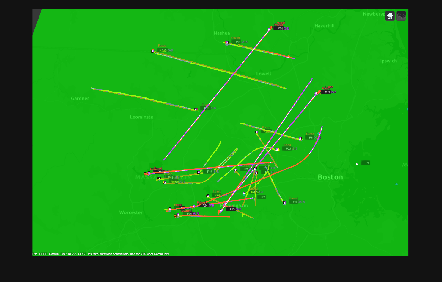

snapshot(mapViewer);

## Collect Error Metrics

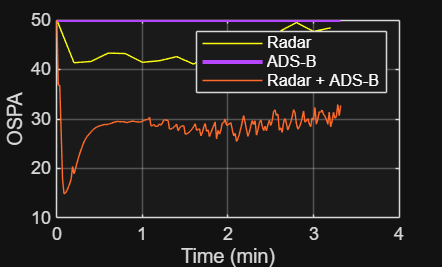

ospa = trackOSPAMetric('CutoffDistance',50);
radarospa = zeros(ceil(numel(radarTrackLog)/12),1);

% Compute radar tracker OSPA
for i=1:12:numel(radarTrackLog)
    tracks = radarTrackLog{i};
    truths = truePoseGPSAll{i}; % Consider omitting the sensor platforms
    for j = 1:length(truths)
        pos = truths(j).Position;
        truths(j).Position = lla2ned(pos,mapOrigin,'ellipsoid');
    end
    radarospa(i) = ospa(tracks, truths);
end

% Compute ADS-B OSPA
adsbospa = zeros(numel(adsbTrackLog),1);
reset(ospa);
for i=1:numel(adsbTrackLog)
    tracks = adsbTrackLog{i};
    truths = truePoseGPSAll{i};
    for j = 1:length(truths)
        pos = truths(j).Position;
        truths(j).Position = lla2ned(pos,mapOrigin,'ellipsoid');
    end
    adsbospa(i) = ospa(tracks, truths);
end

% Compute fused OSPA
fusedospa = zeros(numel(fusedTrackLog),1);
reset(ospa);
for i=1:numel(fusedTrackLog)
    tracks = fusedTrackLog{i};
    truths = truePoseGPSAll{i};
    for j = 1:length(truths)
        pos = truths(j).Position;
        truths(j).Position = lla2ned(pos,mapOrigin,'ellipsoid');
    end
    fusedospa(i) = ospa(tracks, truths);
end

% Plot OSPA
figure
hold on
plot((0:12:(numel(radarTrackLog)-1))/60, radarospa(1:12:end), "Color",radarclr);
plot((0:(numel(adsbTrackLog)-1))/60,adsbospa, "Color", adsbclr, 'LineWidth',2);
plot((0:(numel(fusedTrackLog)-1))/60,fusedospa, "Color", fusedclr);
l=legend('Radar','ADS-B','Radar + ADS-B');
l.Color = [0.1 0.1 0.1];
l.TextColor = [ 1 1 1];
xlabel('Time (min)')
ylabel('OSPA')
ax = gca;
grid on;
box on;
ax.Color = [0.1 0.1 0.1];
ax.GridColor = [1 1 1];

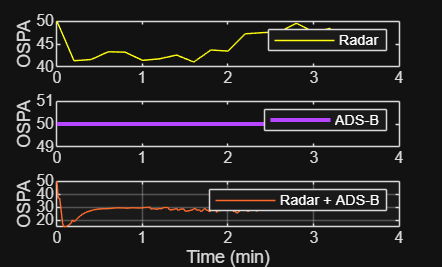

% Plot OSPA Separately
figure
subplot(3,1,1)
plot((0:12:(numel(radarTrackLog)-1))/60, radarospa(1:12:end), "Color",radarclr);
l=legend('Radar');
ylabel('OSPA')

subplot(3,1,2)
plot((0:(numel(adsbTrackLog)-1))/60,adsbospa, "Color", adsbclr, 'LineWidth',2);
yLimits = ylim();
l2=legend('ADS-B');
ylabel('OSPA')

subplot(3,1,3)
plot((0:(numel(fusedTrackLog)-1))/60,fusedospa, "Color", fusedclr);
l3=legend('Radar + ADS-B');
ylabel('OSPA')

l.Color = [0.1 0.1 0.1]; l2.Color = [0.1 0.1 0.1]; l3.Color = [0.1 0.1 0.1];
l.TextColor = [ 1 1 1]; l2.TextColor = [ 1 1 1]; l3.TextColor = [ 1 1 1];
xlabel('Time (min)')
ax = gca;
grid on;
box on;
ax.Color = [0.1 0.1 0.1];
ax.GridColor = [1 1 1];

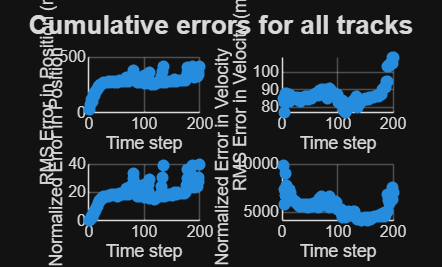

%% Plot RMS values
figure;
timeVec = 1:length(posRMSE);
subplot(2,2,1)
scatter(timeVec,posRMSE,'filled');
xlabel('Time step');
ylabel('RMS Error in Position (m)');
grid('on');

subplot(2,2,2)
scatter(timeVec,velRMSE,'filled');
xlabel('Time step');
ylabel('RMS Error in Velocity (m/s)');
grid('on');

subplot(2,2,3)
scatter(timeVec,posANEES,'filled');
xlabel('Time step');
ylabel('Average Normalized Error in Position');
grid('on');

subplot(2,2,4)
scatter(timeVec,velANEES,'filled');
xlabel('Time step');
ylabel('Average Normalized Error in Velocity');
grid('on');

sgtitle('Cumulative errors for all tracks','FontWeight','bold');

## Helper Functions

**helperCreateScenario**

function scenario = helperCreateScenario(tuningData,mapOrigin)
scenarioDuration = 200; % s
scenario = trackingScenario(UpdateRate=1,StopTime=scenarioDuration,IsEarthCentered=true);
radarTower = platform(scenario, Position=mapOrigin);

rpm = 20;
beamwidthAz = 360; % degrees
fov = [beamwidthAz; 15]; % narrower azimuth FoV
updaterate = 1; % Hz, or match scan revisit rate
activeRadar = fusionRadarSensor(1,"No Scanning", ...
    UpdateRate=updaterate, ...
    FieldOfView=fov, ...
    AzimuthResolution=1.4, ...
    ReferenceRange=111e3, ...
    ReferenceRCS=0, ...
    RangeResolution=135, ...
    HasElevation=true, ...
    HasNoise=true, ...
    HasFalseAlarms=true, ...
    FalseAlarmRate=1e-7,...
    HasRangeRate=true, ...
    RangeRateLimits=[-600 600], ...
    MountingLocation=[0 0 -15], ...
    MountingAngles=[0 0 0], ...
    HasINS=true, ...
    DetectionCoordinates="Sensor spherical");
    

% Mount radar at the top of the tower
radarTower.Sensors = activeRadar;

% Set mechanical elevation scan to begin at 2 degrees above the horizon
elFov = fov(2);
%tilt = 2; % deg
%activeRadar.MechanicalElevationLimits = [-fov(2) 0]-tilt; % deg
activeRadar.FieldOfView(2) = elFov+1e-3;

% Place ADSB Tower
%applehillPos = [-89.5298 2.0521e+03 0]; % NED - isEarthCentered=false
applehillPos = [42.300498, -71.349157 0]; % LLA- isEarthCentered=true
ADSBTower = platform(scenario, Position=applehillPos); %[-5000 -3000 -50]

% Create Platforms for each Aircraft in TuningData
for i = 1:numel(tuningData)
       
    % Geo Trajectory - isEarthCentered = true
    Pos = tuningData{i}.Position;
    time = seconds(tuningData{i}.Time);
    
    % Find indices where time is within the scene duration
    validIdx = time <= scenarioDuration;

    % Truncate time and position vectors
    truncatedTime = time(validIdx);
    truncatedPos = Pos(validIdx, :);
    
    % Generate Trajectory 
    traj = geoTrajectory(truncatedPos,truncatedTime);

    % Create Platform that follows above trajectory 
    platform(scenario,Trajectory=traj);
end
end

**helperCreateTX**

function transponderStruct = helperCreateTX(numPlats,gps)
% helperCreateTX Creates ADS-B transponders for each platform
%   transponderStruct = helperCreateTX(numPlats) returns a struct array of
%   ADS-B transponders, one for each platform, with unique tail numbers.

    % Preallocate struct array
    transponderStruct(numPlats) = struct();

    % Loop through each platform
    for i = 1:numPlats
        tailNumber = sprintf('MW%d', 2019 + i);  % MW2020, MW2021, ...
        
        % Create transponder
        transponderStruct(i).adsbTx = adsbTransponder( ...
            tailNumber, ...
            'UpdateRate', 1, ...
            'GPS', gps, ...
            'Category', adsbCategory.Large);
    end
end

**helperRecordSensorData**

function sensorData = helperRecordSensorData(scenario) %#ok<DEFNU>
if isa(scenario,"trackingScenarioRecording")
    recording = scenario.RecordedData; % We only need the struct
elseif isa(scenario,"struct")
    recording = scenario;
elseif isa(scenario,"trackingScenario") || isa(scenario,"radarScenario")
    seed = 2024; % Change this value if you want a different random number generator seed.
    disp("Recording the scenario to get sensor data. This may take several minutes.");
    recording = record(scenario,"Rotmat",IncludeSensors=true,RecordingFormat="struct",InitialSeed=seed);
else
    error("This example utility function can only be used with a trackingScenario a trackingScenarioRecording");
end

if ~isfield(recording,"SensorConfigurations") || ~isfield(recording,"Detections")
    error("Scenario recording must contain sensor configurations and detections to record sensor data");
end
% Assume all steps have the same sensors.
sensors = recording(1).SensorConfigurations;
detBuffer = vertcat(recording.Detections);
for i = 1:numel(recording)
    for j = 1:numel(recording(i).SensorConfigurations)
        recording(i).SensorConfigurations(j).Time = recording(i).SimulationTime;
    end
end
configBuffer = reshape([recording.SensorConfigurations],[],1);
sensorData = cell(1,numel(sensors));
for k = 1:numel(sensors)
    sensor = sensors(k);
    sensorIdx = sensor.SensorIndex;
    sensorMountingAngles =  eye(3); %rotmat(recording(1).CoverageConfig(k).Orientation,"frame");
    
    detSensorIndex = cellfun(@(x)x.SensorIndex,detBuffer);
    dets = detBuffer(detSensorIndex == sensorIdx);

    cfgSensorIndex = arrayfun(@(x)x.SensorIndex, configBuffer);
    cfgs = configBuffer(cfgSensorIndex == sensorIdx);
    if sensor.MeasurementParameters(1).HasRange
        sensorData{k} = recordMonostaticData(sensorMountingAngles, dets, cfgs);
    else
        %sensorData{k} = recordESMData(sensorMountingAngles, dets, cfgs);
        disp('no ESM sensor, not recording')
    end
end
end

**recordMonostaticData**

function activeRadarData = recordMonostaticData(sensorMountingAngles, detections, cfgs)
% Reported config information
lookMountRot = cell(numel(cfgs),1);
for i = 1:numel(cfgs)
    if cfgs(i).MeasurementParameters(1).IsParentToChild
        lookMountRot{i} = cfgs(i).MeasurementParameters(1).Orientation;
    else
        lookMountRot{i} = cfgs(i).MeasurementParameters(1).Orientation';
    end
end
beamRot = cellfun(@(x)x*sensorMountingAngles',lookMountRot,UniformOutput=false);
ypr = cellfun(@(x)fusion.internal.frames.rotmat2ypr(x,"degrees"),beamRot,UniformOutput=false);
lookTime = arrayfun(@(x)x.Time,cfgs);
lookAzimuth = cellfun(@(x)x(1),ypr);
lookElevation = cellfun(@(x)-x(2),ypr);

% Reported measurement information
detectionTime = cellfun(@(x)x.Time,detections);
azimuth = cellfun(@(x)x.Measurement(1),detections);
elevation = cellfun(@(x)x.Measurement(2),detections);
range = cellfun(@(x)x.Measurement(3),detections);
rangeRate = cellfun(@(x)x.Measurement(4),detections);
azimuthAccuracy =  cellfun(@(x)x.MeasurementNoise(1,1),detections);
elevationAccuracy =  cellfun(@(x)x.MeasurementNoise(2,2),detections);
rangeAccuracy =  cellfun(@(x)x.MeasurementNoise(3,3),detections);
rangeRateAccuracy =  cellfun(@(x)x.MeasurementNoise(4,4),detections);

activeRadarData = struct(LookTime=lookTime(:)',LookAzimuth=lookAzimuth(:)', ...
    LookElevation=lookElevation(:)', DetectionTime=detectionTime(:)', ...
    Azimuth=azimuth(:)',Elevation=elevation(:)', Range=range(:)', ...
    RangeRate=rangeRate(:)',AzimuthAccuracy=sqrt(azimuthAccuracy(:)'), ...
    ElevationAccuracy=sqrt(elevationAccuracy(:)'),RangeAccuracy=sqrt(rangeAccuracy(:)'), ...
    RangeRateAccuracy=sqrt(rangeRateAccuracy(:)'));
end



`helperSyncSensor2spec` - A helper to synchronize sensor properties to the sensor specification

function spec = helperSyncSensor2spec(sensor,spec)
if isa(sensor,'fusionRadarSensor') && strcmpi(sensor.DetectionMode,'monostatic')
    spec = syncRadar2spec(sensor,spec);
elseif isa(sensor,'fusionRadarSensor') && strcmpi(sensor.DetectionMode,'esm')
    spec = syncESM2spec(sensor,spec);
end
end

function spec = syncRadar2spec(sensor,spec)
spec.MountingLocation = sensor.MountingLocation;
spec.MountingAngles = sensor.MountingAngles;
spec.HasElevation = sensor.HasElevation;
spec.HasRangeRate = sensor.HasRangeRate;
spec.FieldOfView = sensor.FieldOfView;
spec.RangeLimits = sensor.RangeLimits;
spec.RangeRateLimits = sensor.RangeRateLimits;
spec.AzimuthResolution = sensor.AzimuthResolution;
spec.RangeResolution = sensor.RangeResolution;
spec.ElevationResolution = sensor.ElevationResolution;
spec.RangeRateResolution = sensor.RangeRateResolution;
spec.DetectionProbability = sensor.DetectionProbability;
spec.FalseAlarmRate = sensor.FalseAlarmRate;
end

function spec = syncESM2spec(sensor,spec)
spec.MountingLocation = sensor.MountingLocation;
spec.MountingAngles = sensor.MountingAngles;
spec.HasElevation = sensor.HasElevation;
spec.FieldOfView = sensor.FieldOfView;
spec.AzimuthResolution = sensor.AzimuthResolution;
spec.ElevationResolution = sensor.ElevationResolution;
spec.DetectionProbability = sensor.DetectionProbability;
spec.FalseAlarmRate = sensor.FalseAlarmRate;
end


**helperSplitSensorData** - A helper to split recorded sensor data to the tracker update interval

function varargout=helperSplitSensorData(sensorData,stopTime,trackerInterval)
varargout = cell(1,nargout);
if iscell(sensorData)
    varargout = cellfun(@(s) splitOneSensorData(s,stopTime,trackerInterval), sensorData, UniformOutput=false);
else
    varargout{1} = splitOneSensorData(sensorData,stopTime,trackerInterval);
end
end

function data=splitOneSensorData(sensorData,stopTime,trackerInterval)
frameTime = 0;
ind = 1;
numFrames = ceil(stopTime/trackerInterval);
data = repmat(sensorData,numFrames,1);
while frameTime < stopTime
    withinInterval = sensorData.LookTime >= frameTime & sensorData.LookTime < frameTime+trackerInterval;
    data(ind).LookTime = sensorData.LookTime(withinInterval);
    data(ind).LookAzimuth = sensorData.LookAzimuth(withinInterval);
    data(ind).LookElevation = sensorData.LookElevation(withinInterval);
    withinInterval = sensorData.DetectionTime >=frameTime & sensorData.DetectionTime < frameTime+trackerInterval;
    data(ind).DetectionTime = sensorData.DetectionTime(withinInterval);
    if isfield(sensorData,"Azimuth")
        data(ind).Azimuth = sensorData.Azimuth(1,withinInterval);
        data(ind).AzimuthAccuracy = sensorData.AzimuthAccuracy(1,withinInterval);
    end
    if isfield(sensorData,"Elevation")
        data(ind).Elevation = sensorData.Elevation(1,withinInterval);
        data(ind).ElevationAccuracy = sensorData.ElevationAccuracy(1,withinInterval);
    end
    if isfield(sensorData,"Range")
        data(ind).Range = sensorData.Range(1,withinInterval);
        data(ind).RangeAccuracy = sensorData.RangeAccuracy(1,withinInterval);
    end
    if isfield(sensorData,"RangeRate")
        data(ind).RangeRate = sensorData.RangeRate(1,withinInterval);
        data(ind).RangeRateAccuracy = sensorData.RangeRateAccuracy(1,withinInterval);
    end
    if isfield(sensorData,"TargetIndex")
        data(ind).TargetIndex = sensorData.TargetIndex(1,withinInterval);
    end
    frameTime = frameTime + trackerInterval;
    ind = ind + 1;
end
end


**helperSavePlatformPoses** - Record platform poses at tracker update timestamps

function platformPoses = helperSavePlatformPoses(scenario,trackerInterval)
endind = ceil(scenario.StopTime/trackerInterval);
samplePose = struct(PlatformID=1,ClassID=0,Position=zeros(1,3),Velocity=zeros(1,3),Acceleration=zeros(1,3),Orientation=eye(3),AngularVelocity=zeros(1,3));
platformPoses = repmat(samplePose,numel(scenario.Platforms),endind);
sampleTimes = trackerInterval*(1:endind);

for p = 1:numel(scenario.Platforms)
    thisPlatform = scenario.Platforms{p};
    trajectory = thisPlatform.Trajectory;
    if isa(trajectory,"waypointTrajectory")
        [position,orientation,velocity,acceleration,angularVelocity] = lookupPose(trajectory,sampleTimes);
        orientation = rotmat(orientation,"frame");
        for i = 1:endind
            platformPoses(p,i) = struct(PlatformID=thisPlatform.PlatformID,ClassID=thisPlatform.ClassID, ...
                Position=position(i,:),Velocity=velocity(i,:),Acceleration=acceleration(i,:), ...
                Orientation=orientation(:,:,i),AngularVelocity=angularVelocity(i,:));
        end
    else % Assumes that non waypointTrajectory means stationary object
        platformPoses(p,:) = repmat(struct(PlatformID=thisPlatform.PlatformID,ClassID=thisPlatform.ClassID, ...
            Position=thisPlatform.Position,Velocity=zeros(1,3),Acceleration=zeros(1,3),Orientation=thisPlatform.Orientation, ...
            AngularVelocity=zeros(1,3)),1,endind);
    end
end
end

**radar2central**

function centralTrack = radar2central(radarTrack)
mapOrigin = [42.39423231362 -70.95934958874 0];
% Initialize a track of the correct state size
centralTrack = objectTrack('State',zeros(6,1),...
    'StateCovariance',eye(6));

% Sync properties of radarTrack except State and StateCovariance with
% radarTrack See syncTrack defined below.
centralTrack = syncTrack(centralTrack,radarTrack);

% Convert NED state to ECEF state
radarState = radarTrack.State;
[X,Y,Z] = ned2ecef(radarState(1),radarState(3),radarState(5),mapOrigin(1),mapOrigin(2),mapOrigin(3),wgs84Ellipsoid); 

% Convert degrees to radians
latRad = deg2rad(mapOrigin(1)); % Lat of mapOrigin
lonRad = deg2rad(mapOrigin(2)); % Lon of mapOrigin

% Rotation matrix from NED to ECEF using mapOrigin lat and lon
R = [-sin(latRad)*cos(lonRad), -sin(latRad)*sin(lonRad),  cos(latRad);  % North Axis in ECEF
    -sin(lonRad),              cos(lonRad),              0;            % East Axis in ECEF
    -cos(latRad)*cos(lonRad), -cos(latRad)*sin(lonRad), -sin(latRad)]; % Down Axis in ECEF

velos = R*[radarState(2),radarState(4),radarState(6)]';
centerState = [X, velos(1), Y, velos(2), Z, velos(3)];

% Convert NED state COVARIANCE to ECEF state COVARIANCE
radarStateCov = radarTrack.StateCovariance;

% Permutation indices: from [x vx y vy z vz] to [x y z vx vy vz]
permute_idx = [1, 3, 5, 2, 4, 6];
unpermute_idx = [1, 4, 2, 5, 3, 6];

% Permute covariance matrix
P_perm = radarStateCov(permute_idx, permute_idx);

% Build block-diagonal rotation matrix
R6 = blkdiag(R, R);

% Rotate the permuted covariance
P_rot = R6 * P_perm * R6';

% Unpermute back to original interleaved format
centerStateCov = P_rot(unpermute_idx, unpermute_idx);

% Set state and covariance of central track
centralTrack.State = centerState;
centralTrack.StateCovariance = centerStateCov;
end

**central2radar**

function radarTrack = central2radar(centralTrack)
% A function to transform a track in the central state-space to a track in
% the radar state-space.
mapOrigin = [42.39423231362 -70.95934958874 0];
% Initialize a track of the correct state size
radarTrack = objectTrack('State',zeros(6,1),...
    'StateCovariance',eye(6));

% Sync properties of radarTrack except State and StateCovariance with
% radarTrack See syncTrack defined below.
radarTrack = syncTrack(radarTrack,centralTrack);

% Convert ECEF state to NED
centerState = centralTrack.State;
[N,E,D] = ecef2ned(centerState(1),centerState(3),centerState(5),mapOrigin(1),mapOrigin(2),mapOrigin(3),wgs84Ellipsoid );

% Convert degrees to radians
latRad = deg2rad(mapOrigin(1)); % Lat of mapOrigin
lonRad = deg2rad(mapOrigin(2)); % Lon of mapOrigin

% Rotation matrix from NED to ECEF using mapOrigin lat and lon
R = [-sin(latRad)*cos(lonRad), -sin(latRad)*sin(lonRad),  cos(latRad);  % North Axis in ECEF
    -sin(lonRad),              cos(lonRad),              0;            % East Axis in ECEF
    -cos(latRad)*cos(lonRad), -cos(latRad)*sin(lonRad), -sin(latRad)]; % Down Axis in ECEF
R = transpose(R); % Inverse operation of the R formulated above, which matches the NED to ECEF rotation

% Use the rotation matrix to convert velocities and reconstruct the state
velos = R*[centerState(2),centerState(4),centerState(6)]';
radarState = [N, velos(1),E,velos(2),D, velos(3)];

% Convert NED state COVARIANCE to ECEF state COVARIANCE
centerStateCov = centralTrack.StateCovariance;

% Permutation indices: from [x vx y vy z vz] to [x y z vx vy vz]
permute_idx = [1, 3, 5, 2, 4, 6];
unpermute_idx = [1, 4, 2, 5, 3, 6];

% Permute covariance matrix
P_perm = centerStateCov(permute_idx, permute_idx);


% Build block-diagonal rotation matrix
R6 = blkdiag(R, R);

% Rotate the permuted covariance
P_rot = R6 * P_perm * R6';

% Unpermute back to original interleaved format
radarStateCov = P_rot(unpermute_idx, unpermute_idx);

% Set state and covariance of radar track
radarTrack.State = radarState;
radarTrack.StateCovariance = radarStateCov;
end

**syncTrack**

function tr1 = syncTrack(tr1,tr2)
% A function to syncs properties of one track with another except the
% "State" and "StateCovariance" property
props = {...
    'TrackID', ...
    'BranchID', ...
    'SourceIndex', ...
    'UpdateTime', ...
    'Age', ...
    'StateParameters', ...
    'ObjectClassID', ...
    'IsConfirmed', ...
    'IsCoasted', ...
    'IsSelfReported', ...
    'ObjectAttributes'}; % Omit: 'TrackLogicState', ...
for i = 1:numel(props)
    tr1.(props{i}) = tr2.(props{i});
end
end

**testCoordinateConversion**

function testCoordinateConversion(numTracks)
    % Map origin (same as your functions)
    mapOrigin = [42.39423231362 -70.95934958874 0];
    wgs84 = wgs84Ellipsoid;

    % Preallocate error arrays
    posErrors = zeros(numTracks,1);
    velErrors = zeros(numTracks,1);
    posRelErrors = zeros(numTracks,1);
    velRelErrors = zeros(numTracks,1);
    covErrors = zeros(numTracks,1);

    % Generate synthetic tracks
    tracks = cell(numTracks,1);
    for i = 1:numTracks
        % Random ECEF position near Boston area
        lat = mapOrigin(1) + 0.001*randn;
        lon = mapOrigin(2) + 0.001*randn;
        alt = 10 + randn; % meters
        [X,Y,Z] = geodetic2ecef(wgs84, lat, lon, alt);

        % Random velocity in m/s
        vx = 10*randn; vy = 10*randn; vz = 2*randn;

        % State and covariance
        state = [X vx Y vy Z vz];
        cov = diag([1 0.1 1 0.1 1 0.1]); % small uncertainty

        % Create objectTrack
        tracks{i} = objectTrack('State', state, 'StateCovariance', cov);
    end

    % Arrays for scatter plots
    origPos = zeros(numTracks,3);
    recPos = zeros(numTracks,3);
    origVel = zeros(numTracks,3);
    recVel = zeros(numTracks,3);

    % Loop through tracks and test round-trip
    for i = 1:numTracks
        centralTrack = tracks{i};

        % Convert to radar and back
        radarTrack = central2radar(centralTrack);
        recoveredTrack = radar2central(radarTrack);

        % Extract positions and velocities
        origPos(i,:) = centralTrack.State([1 3 5]);
        recPos(i,:)  = recoveredTrack.State([1 3 5]);
        origVel(i,:) = centralTrack.State([2 4 6]);
        recVel(i,:)  = recoveredTrack.State([2 4 6]);

        % Compute absolute errors
        posErrors(i) = norm(origPos(i,:) - recPos(i,:));
        velErrors(i) = norm(origVel(i,:) - recVel(i,:));
        covErrors(i) = norm(centralTrack.StateCovariance - recoveredTrack.StateCovariance, 'fro');

        % Compute relative errors (percentage)
        posRelErrors(i) = (posErrors(i) / norm(origPos(i,:))) * 100;
        velRelErrors(i) = (velErrors(i) / norm(origVel(i,:))) * 100;
    end

    % Display summary
    fprintf('Mean Position Error: %.6f m (%.3f%%)\n', mean(posErrors), mean(posRelErrors));
    fprintf('Mean Velocity Error: %.6f m/s (%.3f%%)\n', mean(velErrors), mean(velRelErrors));
    fprintf('Mean Covariance Frobenius Norm Diff: %.6f\n', mean(covErrors));

    % Plot error distributions
    figure;
    subplot(3,1,1); histogram(posErrors); title('Position Error (m)');
    subplot(3,1,2); histogram(velErrors); title('Velocity Error (m/s)');
    subplot(3,1,3); histogram(covErrors); title('Covariance Difference');

    % Scatter plots for visual verification
    figure;
    subplot(1,2,1);
    scatter3(origPos(:,1), origPos(:,2), origPos(:,3), 'b', 'filled'); hold on;
    scatter3(recPos(:,1), recPos(:,2), recPos(:,3), 'r'); grid on;
    title('Original vs Recovered Positions');
    xlabel('X'); ylabel('Y'); zlabel('Z');
    legend('Original','Recovered');

    subplot(1,2,2);
    scatter3(origVel(:,1), origVel(:,2), origVel(:,3), 'b', 'filled'); hold on;
    scatter3(recVel(:,1), recVel(:,2), recVel(:,3), 'r'); grid on;
    title('Original vs Recovered Velocities');
    xlabel('Vx'); ylabel('Vy'); zlabel('Vz');
    legend('Original','Recovered');

    % Check orthogonality of rotation matrix in your functions
    latRad = deg2rad(mapOrigin(1));
    lonRad = deg2rad(mapOrigin(2));
    R = [-sin(latRad)*cos(lonRad), -sin(latRad)*sin(lonRad),  cos(latRad);
         -sin(lonRad),              cos(lonRad),              0;
         -cos(latRad)*cos(lonRad), -cos(latRad)*sin(lonRad), -sin(latRad)];
    fprintf('Rotation matrix orthogonality check: %.6e\n', norm(R'*R - eye(3)));
end


**convertToObjectTrack**

function tracksObj = convertToObjectTrack(tracksStruct)
    tracksObj = repmat(objectTrack, numel(tracksStruct), 1);
    for i = 1:numel(tracksStruct)
        tracksObj(i) = objectTrack( ...
            'TrackID', tracksStruct(i).TrackID, ...
            'BranchID', tracksStruct(i).BranchID, ...
            'SourceIndex', tracksStruct(i).SourceIndex, ...
            'UpdateTime', tracksStruct(i).UpdateTime, ...
            'Age', tracksStruct(i).Age, ...
            'State', tracksStruct(i).State, ...
            'StateCovariance', tracksStruct(i).StateCovariance, ...
            'StateParameters', tracksStruct(i).StateParameters, ...
            'ObjectClassID', tracksStruct(i).ObjectClassID, ...
            'ObjectClassProbabilities', tracksStruct(i).ObjectClassProbabilities, ...
            'TrackLogic', tracksStruct(i).TrackLogic, ...
            'TrackLogicState', tracksStruct(i).TrackLogicState, ...
            'IsConfirmed', tracksStruct(i).IsConfirmed, ...
            'IsCoasted', tracksStruct(i).IsCoasted, ...
            'IsSelfReported', tracksStruct(i).IsSelfReported, ...
            'ObjectAttributes', tracksStruct(i).ObjectAttributes ...
        );
    end
end